# 分からなかった計算について

Weyl代数の表現への埋込を構成して、計算を検証した。

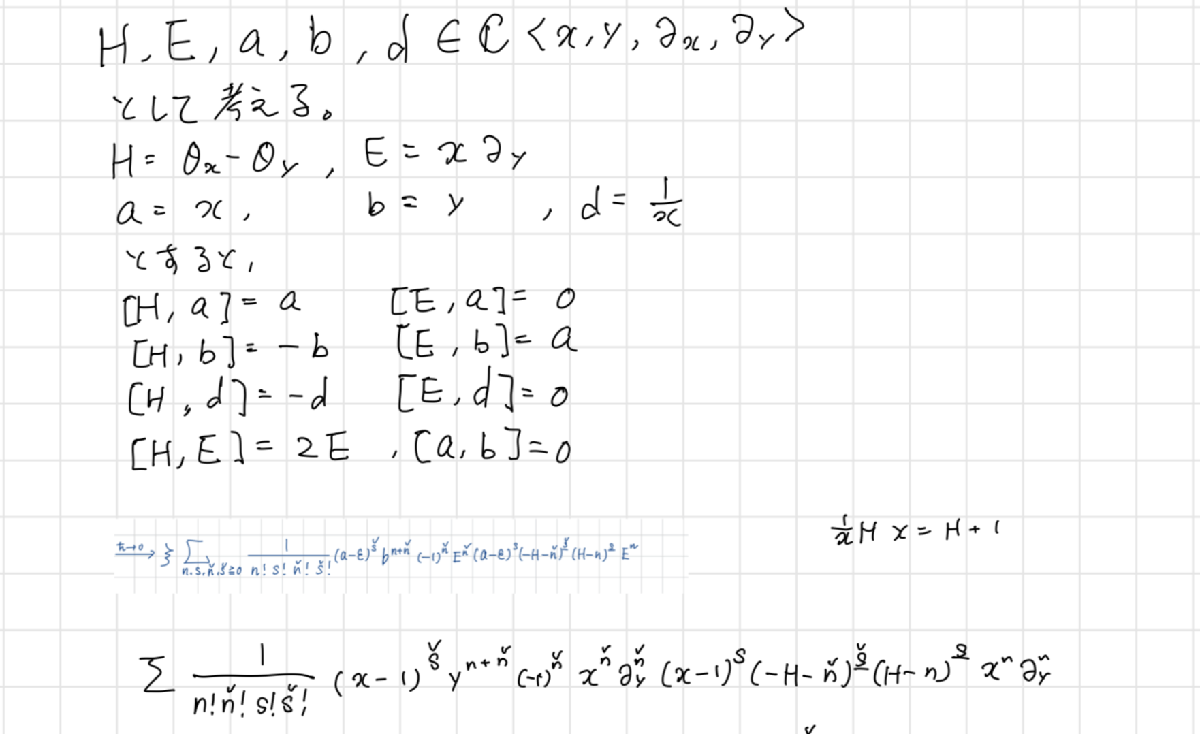

#### Weyl代数の生成元を定義する

(X,D),(Y,J)は変数と微分演算子の組である。4dimのWeyl代数はこれらの元から生成される。

X(1)=X, X(2)=Y, D(1)=D, D(2)=Jである。

[O,X,D]=WeylAlg.getGenerator(2,["X" "Y" "D" "J"])

O =     coeff    X    Y    D    J
    _____    _    _    _    _
      0      0    0    0    0

X =     coeff    X    Y    D    J
    _____    _    _    _    _
      1      1    0    0    0
    coeff    X    Y    D    J
    _____    _    _    _    _
      1      0    1    0    0

D =     coeff    X    Y    D    J
    _____    _    _    _    _
      1      0    0    1    0
    coeff    X    Y    D    J
    _____    _    _    _    _
      1      0    0    0    1

#### 代数Aの表現を構成する

Th=arrayfun(@(x,y)x*y,X,D);
H=Th(1)-Th(2);
E=X(1)*D(2);
a=X(1);
b=X(2);

#### 式を計算する

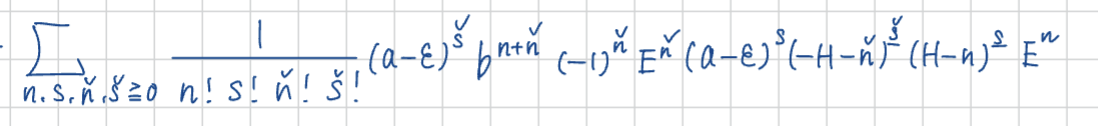

operand=@(n,nc,s,sc)1/prod(factorial([n nc s sc]))*(a-1)^(sc+s)*b^(n+nc)*(-E)^nc...
    *FP(-H-nc,sc)*FP(H-n,s)*E^n

operand = 値をもつ function_handle :
    @(n,nc,s,sc)1/prod(factorial([n,nc,s,sc]))*(a-1)^(sc+s)*b^(n+nc)*(-E)^nc*FP(-H-nc,sc)*FP(H-n,s)*E^n

operand(0,0,0,1)

ans =     coeff    X    Y    D    J
    _____    _    _    _    _
     -1      0    1    0    1
      1      1    0    1    0
      1      1    1    0    1
     -1      2    0    1    0

FP(X(1),3)

ans =     coeff    X    Y    D    J
    _____    _    _    _    _
      2      1    0    0    0
     -3      2    0    0    0
      1      3    0    0    0

summation=O;
Acc=O;
n=2;
nc=2;
s=3;
sc=3;
Co=table2cell(combinations(0:n,0:nc,0:s,0:sc));
for ii=1:height(Co)
    [n,nc,s,sc]=deal(Co{ii,:});
    S=operand(n,nc,s,sc);
    fprintf('case:(n,nc,s,sc)=(%d,%d,%d,%d)\n',n,nc,s,sc)
    disp(sym(S))
    Acc(end+1)=S;
    summation=summation+S;
end

case:(n,nc,s,sc)=(0,0,0,0)


$$1$$

case:(n,nc,s,sc)=(0,0,0,1)


$$\left(J\,Y-\text{D}\,X\right)\,\left(X-1\right)$$

case:(n,nc,s,sc)=(0,0,0,2)


$$\frac{{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{2}\,Y^{2}\right)}{2}$$

case:(n,nc,s,sc)=(0,0,0,3)


$$-\frac{{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+6\,\text{D}\,X-J^{3}\,Y^{3}\right)}{6}$$

case:(n,nc,s,sc)=(0,0,1,0)


$$-\left(J\,Y-\text{D}\,X\right)\,\left(X-1\right)$$

case:(n,nc,s,sc)=(0,0,1,1)


$$-{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+\text{D}\,X+J^{2}\,Y^{2}+J\,Y\right)$$

case:(n,nc,s,sc)=(0,0,1,2)


$$\frac{{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+4\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-2\,\text{D}\,J\,X\,Y+2\,\text{D}\,X-J^{3}\,Y^{3}-2\,J^{2}\,Y^{2}\right)}{2}$$

case:(n,nc,s,sc)=(0,0,1,3)


$$-\frac{{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+9\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-15\,{\text{D}}^{2}\,J\,X^{2}\,Y+18\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+6\,\text{D}\,X+J^{4}\,Y^{4}+3\,J^{3}\,Y^{3}\right)}{6}$$

case:(n,nc,s,sc)=(0,0,2,0)


$$\frac{{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+J^{2}\,Y^{2}+2\,J\,Y\right)}{2}$$

case:(n,nc,s,sc)=(0,0,2,1)


$$\frac{{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-2\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-2\,\text{D}\,J\,X\,Y+J^{3}\,Y^{3}+4\,J^{2}\,Y^{2}+2\,J\,Y\right)}{2}$$

case:(n,nc,s,sc)=(0,0,2,2)


$$\frac{{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+6\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-6\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-6\,\text{D}\,J^{2}\,X\,Y^{2}+J^{4}\,Y^{4}+6\,J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}\right)}{4}$$

case:(n,nc,s,sc)=(0,0,2,3)


$$-\frac{{\left(X-1\right)}^{5}\,\left({\text{D}}^{5}\,X^{5}-5\,{\text{D}}^{4}\,J\,X^{4}\,Y+12\,{\text{D}}^{4}\,X^{4}+10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}-28\,{\text{D}}^{3}\,J\,X^{3}\,Y+36\,{\text{D}}^{3}\,X^{3}-10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+12\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-24\,{\text{D}}^{2}\,J\,X^{2}\,Y+24\,{\text{D}}^{2}\,X^{2}+5\,\text{D}\,J^{4}\,X\,Y^{4}+12\,\text{D}\,J^{3}\,X\,Y^{3}-J^{5}\,Y^{5}-8\,J^{4}\,Y^{4}-12\,J^{3}\,Y^{3}\right)}{12}$$

case:(n,nc,s,sc)=(0,0,3,0)


$$-\frac{{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}+6\,J\,Y\right)}{6}$$

case:(n,nc,s,sc)=(0,0,3,1)


$$-\frac{{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+3\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-4\,\text{D}\,J^{3}\,X\,Y^{3}-15\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+J^{4}\,Y^{4}+9\,J^{3}\,Y^{3}+18\,J^{2}\,Y^{2}+6\,J\,Y\right)}{6}$$

case:(n,nc,s,sc)=(0,0,3,2)


$$-\frac{{\left(X-1\right)}^{5}\,\left(-{\text{D}}^{5}\,X^{5}+5\,{\text{D}}^{4}\,J\,X^{4}\,Y-8\,{\text{D}}^{4}\,X^{4}-10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}+12\,{\text{D}}^{3}\,J\,X^{3}\,Y-12\,{\text{D}}^{3}\,X^{3}+10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+12\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-5\,\text{D}\,J^{4}\,X\,Y^{4}-28\,\text{D}\,J^{3}\,X\,Y^{3}-24\,\text{D}\,J^{2}\,X\,Y^{2}+J^{5}\,Y^{5}+12\,J^{4}\,Y^{4}+36\,J^{3}\,Y^{3}+24\,J^{2}\,Y^{2}\right)}{12}$$

case:(n,nc,s,sc)=(0,0,3,3)


$$-\frac{{\left(X-1\right)}^{6}\,\left({\text{D}}^{6}\,X^{6}-6\,{\text{D}}^{5}\,J\,X^{5}\,Y+15\,{\text{D}}^{5}\,X^{5}+15\,{\text{D}}^{4}\,J^{2}\,X^{4}\,Y^{2}-45\,{\text{D}}^{4}\,J\,X^{4}\,Y+60\,{\text{D}}^{4}\,X^{4}-20\,{\text{D}}^{3}\,J^{3}\,X^{3}\,Y^{3}+30\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}-60\,{\text{D}}^{3}\,J\,X^{3}\,Y+60\,{\text{D}}^{3}\,X^{3}+15\,{\text{D}}^{2}\,J^{4}\,X^{2}\,Y^{4}+30\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}-6\,\text{D}\,J^{5}\,X\,Y^{5}-45\,\text{D}\,J^{4}\,X\,Y^{4}-60\,\text{D}\,J^{3}\,X\,Y^{3}+J^{6}\,Y^{6}+15\,J^{5}\,Y^{5}+60\,J^{4}\,Y^{4}+60\,J^{3}\,Y^{3}\right)}{36}$$

case:(n,nc,s,sc)=(0,1,0,0)


$$-J\,X\,Y$$

case:(n,nc,s,sc)=(0,1,0,1)


$$-J\,X\,Y\,\left(J\,Y-\text{D}\,X\right)\,\left(X-1\right)$$

case:(n,nc,s,sc)=(0,1,0,2)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{2}\,Y^{2}\right)}{2}$$

case:(n,nc,s,sc)=(0,1,0,3)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+6\,\text{D}\,X-J^{3}\,Y^{3}\right)}{6}$$

case:(n,nc,s,sc)=(0,1,1,0)


$$J\,X\,Y\,\left(X-1\right)\,\left(J\,Y-\text{D}\,X+1\right)$$

case:(n,nc,s,sc)=(0,1,1,1)


$$J\,X\,Y\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+J^{2}\,Y^{2}+2\,J\,Y\right)$$

case:(n,nc,s,sc)=(0,1,1,2)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+3\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-J^{3}\,Y^{3}-3\,J^{2}\,Y^{2}\right)}{2}$$

case:(n,nc,s,sc)=(0,1,1,3)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+8\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-12\,{\text{D}}^{2}\,J\,X^{2}\,Y+12\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+J^{4}\,Y^{4}+4\,J^{3}\,Y^{3}\right)}{6}$$

case:(n,nc,s,sc)=(0,1,2,0)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y-2\,\text{D}\,X+J^{2}\,Y^{2}+4\,J\,Y+2\right)}{2}$$

case:(n,nc,s,sc)=(0,1,2,1)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}+6\,J\,Y\right)}{2}$$

case:(n,nc,s,sc)=(0,1,2,2)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+4\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-12\,\text{D}\,J^{2}\,X\,Y^{2}+J^{4}\,Y^{4}+8\,J^{3}\,Y^{3}+12\,J^{2}\,Y^{2}\right)}{4}$$

case:(n,nc,s,sc)=(0,1,2,3)


case:(n,nc,s,sc)=(0,1,3,0)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+3\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y-6\,\text{D}\,X+J^{3}\,Y^{3}+9\,J^{2}\,Y^{2}+18\,J\,Y+6\right)}{6}$$

case:(n,nc,s,sc)=(0,1,3,1)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+12\,{\text{D}}^{2}\,J\,X^{2}\,Y-4\,\text{D}\,J^{3}\,X\,Y^{3}-24\,\text{D}\,J^{2}\,X\,Y^{2}-24\,\text{D}\,J\,X\,Y+J^{4}\,Y^{4}+12\,J^{3}\,Y^{3}+36\,J^{2}\,Y^{2}+24\,J\,Y\right)}{6}$$

case:(n,nc,s,sc)=(0,1,3,2)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{5}\,\left(-{\text{D}}^{5}\,X^{5}+5\,{\text{D}}^{4}\,J\,X^{4}\,Y-5\,{\text{D}}^{4}\,X^{4}-10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}+10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+30\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-5\,\text{D}\,J^{4}\,X\,Y^{4}-40\,\text{D}\,J^{3}\,X\,Y^{3}-60\,\text{D}\,J^{2}\,X\,Y^{2}+J^{5}\,Y^{5}+15\,J^{4}\,Y^{4}+60\,J^{3}\,Y^{3}+60\,J^{2}\,Y^{2}\right)}{12}$$

case:(n,nc,s,sc)=(0,1,3,3)


case:(n,nc,s,sc)=(0,2,0,0)


$$\frac{J^{2}\,X^{2}\,Y^{2}}{2}$$

case:(n,nc,s,sc)=(0,2,0,1)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,\left(J\,Y-\text{D}\,X\right)\,\left(X-1\right)}{2}$$

case:(n,nc,s,sc)=(0,2,0,2)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{2}\,Y^{2}\right)}{4}$$

case:(n,nc,s,sc)=(0,2,0,3)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+6\,\text{D}\,X-J^{3}\,Y^{3}\right)}{12}$$

case:(n,nc,s,sc)=(0,2,1,0)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,\left(X-1\right)\,\left(J\,Y-\text{D}\,X+2\right)}{2}$$

case:(n,nc,s,sc)=(0,2,1,1)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y-\text{D}\,X+J^{2}\,Y^{2}+3\,J\,Y\right)}{2}$$

case:(n,nc,s,sc)=(0,2,1,2)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+2\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}+2\,\text{D}\,J\,X\,Y-2\,\text{D}\,X-J^{3}\,Y^{3}-4\,J^{2}\,Y^{2}\right)}{4}$$

case:(n,nc,s,sc)=(0,2,1,3)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+7\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-9\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-3\,\text{D}\,J^{2}\,X\,Y^{2}+6\,\text{D}\,J\,X\,Y-6\,\text{D}\,X+J^{4}\,Y^{4}+5\,J^{3}\,Y^{3}\right)}{12}$$

case:(n,nc,s,sc)=(0,2,2,0)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y-4\,\text{D}\,X+J^{2}\,Y^{2}+6\,J\,Y+6\right)}{4}$$

case:(n,nc,s,sc)=(0,2,2,1)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+2\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-10\,\text{D}\,J\,X\,Y-2\,\text{D}\,X+J^{3}\,Y^{3}+8\,J^{2}\,Y^{2}+12\,J\,Y\right)}{4}$$

case:(n,nc,s,sc)=(0,2,2,2)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+2\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+6\,{\text{D}}^{2}\,J\,X^{2}\,Y-4\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-18\,\text{D}\,J^{2}\,X\,Y^{2}-4\,\text{D}\,J\,X\,Y+4\,\text{D}\,X+J^{4}\,Y^{4}+10\,J^{3}\,Y^{3}+20\,J^{2}\,Y^{2}\right)}{8}$$

case:(n,nc,s,sc)=(0,2,2,3)


case:(n,nc,s,sc)=(0,2,3,0)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-18\,\text{D}\,J\,X\,Y-18\,\text{D}\,X+J^{3}\,Y^{3}+12\,J^{2}\,Y^{2}+36\,J\,Y+24\right)}{12}$$

case:(n,nc,s,sc)=(0,2,3,1)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y-3\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+21\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-33\,\text{D}\,J^{2}\,X\,Y^{2}-54\,\text{D}\,J\,X\,Y-6\,\text{D}\,X+J^{4}\,Y^{4}+15\,J^{3}\,Y^{3}+60\,J^{2}\,Y^{2}+60\,J\,Y\right)}{12}$$

case:(n,nc,s,sc)=(0,2,3,2)


case:(n,nc,s,sc)=(0,2,3,3)


case:(n,nc,s,sc)=(1,0,0,0)


$$J\,X\,Y$$

case:(n,nc,s,sc)=(1,0,0,1)


$$-J\,X\,Y\,\left(X-1\right)\,\left(\text{D}\,X-J\,Y+1\right)$$

case:(n,nc,s,sc)=(1,0,0,2)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+4\,\text{D}\,X+J^{2}\,Y^{2}-2\,J\,Y+2\right)}{2}$$

case:(n,nc,s,sc)=(1,0,0,3)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+9\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y+18\,\text{D}\,X-J^{3}\,Y^{3}+3\,J^{2}\,Y^{2}-6\,J\,Y+6\right)}{6}$$

case:(n,nc,s,sc)=(1,0,1,0)


$$-J\,X\,Y\,\left(J\,Y-\text{D}\,X\right)\,\left(X-1\right)$$

case:(n,nc,s,sc)=(1,0,1,1)


$$-J\,X\,Y\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{2}\,Y^{2}\right)$$

case:(n,nc,s,sc)=(1,0,1,2)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+6\,\text{D}\,X-J^{3}\,Y^{3}\right)}{2}$$

case:(n,nc,s,sc)=(1,0,1,3)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+12\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-24\,{\text{D}}^{2}\,J\,X^{2}\,Y+36\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+12\,\text{D}\,J^{2}\,X\,Y^{2}-24\,\text{D}\,J\,X\,Y+24\,\text{D}\,X+J^{4}\,Y^{4}\right)}{6}$$

case:(n,nc,s,sc)=(1,0,2,0)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+J^{2}\,Y^{2}+2\,J\,Y\right)}{2}$$

case:(n,nc,s,sc)=(1,0,2,1)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+3\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-J^{3}\,Y^{3}-3\,J^{2}\,Y^{2}\right)}{2}$$

case:(n,nc,s,sc)=(1,0,2,2)


$$\frac{J\,X\,Y\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+8\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-12\,{\text{D}}^{2}\,J\,X^{2}\,Y+12\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+J^{4}\,Y^{4}+4\,J^{3}\,Y^{3}\right)}{4}$$

case:(n,nc,s,sc)=(1,0,2,3)


case:(n,nc,s,sc)=(1,0,3,0)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}+6\,J\,Y\right)}{6}$$

case:(n,nc,s,sc)=(1,0,3,1)


$$-\frac{J\,X\,Y\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+4\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-12\,\text{D}\,J^{2}\,X\,Y^{2}+J^{4}\,Y^{4}+8\,J^{3}\,Y^{3}+12\,J^{2}\,Y^{2}\right)}{6}$$

case:(n,nc,s,sc)=(1,0,3,2)


case:(n,nc,s,sc)=(1,0,3,3)


case:(n,nc,s,sc)=(1,1,0,0)


$$-J^{2}\,X^{2}\,Y^{2}$$

case:(n,nc,s,sc)=(1,1,0,1)


$$J^{2}\,X^{2}\,Y^{2}\,\left(X-1\right)\,\left(\text{D}\,X-J\,Y+1\right)$$

case:(n,nc,s,sc)=(1,1,0,2)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+4\,\text{D}\,X+J^{2}\,Y^{2}-2\,J\,Y+2\right)}{2}$$

case:(n,nc,s,sc)=(1,1,0,3)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+9\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y+18\,\text{D}\,X-J^{3}\,Y^{3}+3\,J^{2}\,Y^{2}-6\,J\,Y+6\right)}{6}$$

case:(n,nc,s,sc)=(1,1,1,0)


$$J^{2}\,X^{2}\,Y^{2}\,\left(X-1\right)\,\left(J\,Y-\text{D}\,X+1\right)$$

case:(n,nc,s,sc)=(1,1,1,1)


$$J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+\text{D}\,X+J^{2}\,Y^{2}+J\,Y-1\right)$$

case:(n,nc,s,sc)=(1,1,1,2)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+5\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-4\,\text{D}\,J\,X\,Y+2\,\text{D}\,X-J^{3}\,Y^{3}-J^{2}\,Y^{2}+2\,J\,Y-2\right)}{2}$$

case:(n,nc,s,sc)=(1,1,1,3)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+11\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-21\,{\text{D}}^{2}\,J\,X^{2}\,Y+27\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+9\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y+6\,\text{D}\,X+J^{4}\,Y^{4}+J^{3}\,Y^{3}-3\,J^{2}\,Y^{2}+6\,J\,Y-6\right)}{6}$$

case:(n,nc,s,sc)=(1,1,2,0)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y-2\,\text{D}\,X+J^{2}\,Y^{2}+4\,J\,Y+2\right)}{2}$$

case:(n,nc,s,sc)=(1,1,2,1)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-4\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{3}\,Y^{3}+5\,J^{2}\,Y^{2}+2\,J\,Y-2\right)}{2}$$

case:(n,nc,s,sc)=(1,1,2,2)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+6\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-6\,{\text{D}}^{2}\,J\,X^{2}\,Y+2\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-6\,\text{D}\,J^{2}\,X\,Y^{2}+8\,\text{D}\,J\,X\,Y-4\,\text{D}\,X+J^{4}\,Y^{4}+6\,J^{3}\,Y^{3}+2\,J^{2}\,Y^{2}-4\,J\,Y+4\right)}{4}$$

case:(n,nc,s,sc)=(1,1,2,3)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{5}\,\left({\text{D}}^{5}\,X^{5}-5\,{\text{D}}^{4}\,J\,X^{4}\,Y+13\,{\text{D}}^{4}\,X^{4}+10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}-32\,{\text{D}}^{3}\,J\,X^{3}\,Y+38\,{\text{D}}^{3}\,X^{3}-10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+18\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-18\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+5\,\text{D}\,J^{4}\,X\,Y^{4}+8\,\text{D}\,J^{3}\,X\,Y^{3}-18\,\text{D}\,J^{2}\,X\,Y^{2}+24\,\text{D}\,J\,X\,Y-12\,\text{D}\,X-J^{5}\,Y^{5}-7\,J^{4}\,Y^{4}-2\,J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-12\,J\,Y+12\right)}{12}$$

case:(n,nc,s,sc)=(1,1,3,0)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+3\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y-6\,\text{D}\,X+J^{3}\,Y^{3}+9\,J^{2}\,Y^{2}+18\,J\,Y+6\right)}{6}$$

case:(n,nc,s,sc)=(1,1,3,1)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+9\,{\text{D}}^{2}\,J\,X^{2}\,Y-3\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-21\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y+6\,\text{D}\,X+J^{4}\,Y^{4}+11\,J^{3}\,Y^{3}+27\,J^{2}\,Y^{2}+6\,J\,Y-6\right)}{6}$$

case:(n,nc,s,sc)=(1,1,3,2)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{5}\,\left(-{\text{D}}^{5}\,X^{5}+5\,{\text{D}}^{4}\,J\,X^{4}\,Y-7\,{\text{D}}^{4}\,X^{4}-10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}+8\,{\text{D}}^{3}\,J\,X^{3}\,Y-2\,{\text{D}}^{3}\,X^{3}+10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+18\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-18\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-5\,\text{D}\,J^{4}\,X\,Y^{4}-32\,\text{D}\,J^{3}\,X\,Y^{3}-18\,\text{D}\,J^{2}\,X\,Y^{2}+24\,\text{D}\,J\,X\,Y-12\,\text{D}\,X+J^{5}\,Y^{5}+13\,J^{4}\,Y^{4}+38\,J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-12\,J\,Y+12\right)}{12}$$

case:(n,nc,s,sc)=(1,1,3,3)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{6}\,\left({\text{D}}^{6}\,X^{6}-6\,{\text{D}}^{5}\,J\,X^{5}\,Y+15\,{\text{D}}^{5}\,X^{5}+15\,{\text{D}}^{4}\,J^{2}\,X^{4}\,Y^{2}-45\,{\text{D}}^{4}\,J\,X^{4}\,Y+51\,{\text{D}}^{4}\,X^{4}-20\,{\text{D}}^{3}\,J^{3}\,X^{3}\,Y^{3}+30\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}-24\,{\text{D}}^{3}\,J\,X^{3}\,Y+6\,{\text{D}}^{3}\,X^{3}+15\,{\text{D}}^{2}\,J^{4}\,X^{2}\,Y^{4}+30\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}-54\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+54\,{\text{D}}^{2}\,J\,X^{2}\,Y-18\,{\text{D}}^{2}\,X^{2}-6\,\text{D}\,J^{5}\,X\,Y^{5}-45\,\text{D}\,J^{4}\,X\,Y^{4}-24\,\text{D}\,J^{3}\,X\,Y^{3}+54\,\text{D}\,J^{2}\,X\,Y^{2}-72\,\text{D}\,J\,X\,Y+36\,\text{D}\,X+J^{6}\,Y^{6}+15\,J^{5}\,Y^{5}+51\,J^{4}\,Y^{4}+6\,J^{3}\,Y^{3}-18\,J^{2}\,Y^{2}+36\,J\,Y-36\right)}{36}$$

case:(n,nc,s,sc)=(1,2,0,0)


$$\frac{J^{3}\,X^{3}\,Y^{3}}{2}$$

case:(n,nc,s,sc)=(1,2,0,1)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,\left(X-1\right)\,\left(\text{D}\,X-J\,Y+1\right)}{2}$$

case:(n,nc,s,sc)=(1,2,0,2)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+4\,\text{D}\,X+J^{2}\,Y^{2}-2\,J\,Y+2\right)}{4}$$

case:(n,nc,s,sc)=(1,2,0,3)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+9\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y+18\,\text{D}\,X-J^{3}\,Y^{3}+3\,J^{2}\,Y^{2}-6\,J\,Y+6\right)}{12}$$

case:(n,nc,s,sc)=(1,2,1,0)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,\left(X-1\right)\,\left(J\,Y-\text{D}\,X+2\right)}{2}$$

case:(n,nc,s,sc)=(1,2,1,1)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+J^{2}\,Y^{2}+2\,J\,Y-2\right)}{2}$$

case:(n,nc,s,sc)=(1,2,1,2)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-4\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}+2\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{3}\,Y^{3}+2\,J^{2}\,Y^{2}-4\,J\,Y+4\right)}{4}$$

case:(n,nc,s,sc)=(1,2,1,3)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+10\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-18\,{\text{D}}^{2}\,J\,X^{2}\,Y+18\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+6\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,X+J^{4}\,Y^{4}+2\,J^{3}\,Y^{3}-6\,J^{2}\,Y^{2}+12\,J\,Y-12\right)}{12}$$

case:(n,nc,s,sc)=(1,2,2,0)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y-4\,\text{D}\,X+J^{2}\,Y^{2}+6\,J\,Y+6\right)}{4}$$

case:(n,nc,s,sc)=(1,2,2,1)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-8\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{3}\,Y^{3}+7\,J^{2}\,Y^{2}+6\,J\,Y-6\right)}{4}$$

case:(n,nc,s,sc)=(1,2,2,2)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+4\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-6\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-12\,\text{D}\,J^{2}\,X\,Y^{2}+12\,\text{D}\,J\,X\,Y+J^{4}\,Y^{4}+8\,J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-12\,J\,Y+12\right)}{8}$$

case:(n,nc,s,sc)=(1,2,2,3)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{5}\,\left({\text{D}}^{5}\,X^{5}-5\,{\text{D}}^{4}\,J\,X^{4}\,Y+11\,{\text{D}}^{4}\,X^{4}+10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}-24\,{\text{D}}^{3}\,J\,X^{3}\,Y+18\,{\text{D}}^{3}\,X^{3}-10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+18\,{\text{D}}^{2}\,J\,X^{2}\,Y-30\,{\text{D}}^{2}\,X^{2}+5\,\text{D}\,J^{4}\,X\,Y^{4}+16\,\text{D}\,J^{3}\,X\,Y^{3}-30\,\text{D}\,J^{2}\,X\,Y^{2}+24\,\text{D}\,J\,X\,Y+12\,\text{D}\,X-J^{5}\,Y^{5}-9\,J^{4}\,Y^{4}-6\,J^{3}\,Y^{3}+18\,J^{2}\,Y^{2}-36\,J\,Y+36\right)}{24}$$

case:(n,nc,s,sc)=(1,2,3,0)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-18\,\text{D}\,J\,X\,Y-18\,\text{D}\,X+J^{3}\,Y^{3}+12\,J^{2}\,Y^{2}+36\,J\,Y+24\right)}{12}$$

case:(n,nc,s,sc)=(1,2,3,1)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y-2\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+18\,{\text{D}}^{2}\,J\,X^{2}\,Y-4\,\text{D}\,J^{3}\,X\,Y^{3}-30\,\text{D}\,J^{2}\,X\,Y^{2}-36\,\text{D}\,J\,X\,Y+12\,\text{D}\,X+J^{4}\,Y^{4}+14\,J^{3}\,Y^{3}+48\,J^{2}\,Y^{2}+24\,J\,Y-24\right)}{12}$$

case:(n,nc,s,sc)=(1,2,3,2)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{5}\,\left({\text{D}}^{5}\,X^{5}-5\,{\text{D}}^{4}\,J\,X^{4}\,Y+4\,{\text{D}}^{4}\,X^{4}+10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}+4\,{\text{D}}^{3}\,J\,X^{3}\,Y-10\,{\text{D}}^{3}\,X^{3}-10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}-36\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+18\,{\text{D}}^{2}\,J\,X^{2}\,Y+12\,{\text{D}}^{2}\,X^{2}+5\,\text{D}\,J^{4}\,X\,Y^{4}+44\,\text{D}\,J^{3}\,X\,Y^{3}+54\,\text{D}\,J^{2}\,X\,Y^{2}-60\,\text{D}\,J\,X\,Y+12\,\text{D}\,X-J^{5}\,Y^{5}-16\,J^{4}\,Y^{4}-62\,J^{3}\,Y^{3}-24\,J^{2}\,Y^{2}+48\,J\,Y-48\right)}{24}$$

case:(n,nc,s,sc)=(1,2,3,3)


case:(n,nc,s,sc)=(2,0,0,0)


$$\frac{J^{2}\,X^{2}\,Y^{2}}{2}$$

case:(n,nc,s,sc)=(2,0,0,1)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,\left(X-1\right)\,\left(\text{D}\,X-J\,Y+2\right)}{2}$$

case:(n,nc,s,sc)=(2,0,0,2)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+6\,\text{D}\,X+J^{2}\,Y^{2}-4\,J\,Y+6\right)}{4}$$

case:(n,nc,s,sc)=(2,0,0,3)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+12\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-18\,\text{D}\,J\,X\,Y+36\,\text{D}\,X-J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-18\,J\,Y+24\right)}{12}$$

case:(n,nc,s,sc)=(2,0,1,0)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,\left(J\,Y-\text{D}\,X\right)\,\left(X-1\right)}{2}$$

case:(n,nc,s,sc)=(2,0,1,1)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+3\,\text{D}\,X+J^{2}\,Y^{2}-J\,Y\right)}{2}$$

case:(n,nc,s,sc)=(2,0,1,2)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+8\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-10\,\text{D}\,J\,X\,Y+12\,\text{D}\,X-J^{3}\,Y^{3}+2\,J^{2}\,Y^{2}-2\,J\,Y\right)}{4}$$

case:(n,nc,s,sc)=(2,0,1,3)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+15\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-33\,{\text{D}}^{2}\,J\,X^{2}\,Y+60\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+21\,\text{D}\,J^{2}\,X\,Y^{2}-54\,\text{D}\,J\,X\,Y+60\,\text{D}\,X+J^{4}\,Y^{4}-3\,J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-6\,J\,Y\right)}{12}$$

case:(n,nc,s,sc)=(2,0,2,0)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+J^{2}\,Y^{2}+2\,J\,Y\right)}{4}$$

case:(n,nc,s,sc)=(2,0,2,1)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+4\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-2\,\text{D}\,J\,X\,Y-J^{3}\,Y^{3}-2\,J^{2}\,Y^{2}+2\,J\,Y\right)}{4}$$

case:(n,nc,s,sc)=(2,0,2,2)


$$\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+10\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-18\,{\text{D}}^{2}\,J\,X^{2}\,Y+20\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+6\,\text{D}\,J^{2}\,X\,Y^{2}-4\,\text{D}\,J\,X\,Y+J^{4}\,Y^{4}+2\,J^{3}\,Y^{3}-4\,J^{2}\,Y^{2}+4\,J\,Y\right)}{8}$$

case:(n,nc,s,sc)=(2,0,2,3)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{5}\,\left({\text{D}}^{5}\,X^{5}-5\,{\text{D}}^{4}\,J\,X^{4}\,Y+18\,{\text{D}}^{4}\,X^{4}+10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}-52\,{\text{D}}^{3}\,J\,X^{3}\,Y+90\,{\text{D}}^{3}\,X^{3}-10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+48\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-114\,{\text{D}}^{2}\,J\,X^{2}\,Y+120\,{\text{D}}^{2}\,X^{2}+5\,\text{D}\,J^{4}\,X\,Y^{4}-12\,\text{D}\,J^{3}\,X\,Y^{3}+18\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y-J^{5}\,Y^{5}-2\,J^{4}\,Y^{4}+6\,J^{3}\,Y^{3}-12\,J^{2}\,Y^{2}+12\,J\,Y\right)}{24}$$

case:(n,nc,s,sc)=(2,0,3,0)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y-3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y+J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}+6\,J\,Y\right)}{12}$$

case:(n,nc,s,sc)=(2,0,3,1)


$$-\frac{J^{2}\,X^{2}\,Y^{2}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+5\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y-4\,\text{D}\,J^{3}\,X\,Y^{3}-9\,\text{D}\,J^{2}\,X\,Y^{2}+6\,\text{D}\,J\,X\,Y+J^{4}\,Y^{4}+7\,J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-6\,J\,Y\right)}{12}$$

case:(n,nc,s,sc)=(2,0,3,2)


case:(n,nc,s,sc)=(2,0,3,3)


case:(n,nc,s,sc)=(2,1,0,0)


$$-\frac{J^{3}\,X^{3}\,Y^{3}}{2}$$

case:(n,nc,s,sc)=(2,1,0,1)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,\left(X-1\right)\,\left(\text{D}\,X-J\,Y+2\right)}{2}$$

case:(n,nc,s,sc)=(2,1,0,2)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+6\,\text{D}\,X+J^{2}\,Y^{2}-4\,J\,Y+6\right)}{4}$$

case:(n,nc,s,sc)=(2,1,0,3)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+12\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-18\,\text{D}\,J\,X\,Y+36\,\text{D}\,X-J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-18\,J\,Y+24\right)}{12}$$

case:(n,nc,s,sc)=(2,1,1,0)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,\left(X-1\right)\,\left(J\,Y-\text{D}\,X+1\right)}{2}$$

case:(n,nc,s,sc)=(2,1,1,1)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+2\,\text{D}\,X+J^{2}\,Y^{2}-2\right)}{2}$$

case:(n,nc,s,sc)=(2,1,1,2)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+7\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-8\,\text{D}\,J\,X\,Y+6\,\text{D}\,X-J^{3}\,Y^{3}+J^{2}\,Y^{2}+2\,J\,Y-6\right)}{4}$$

case:(n,nc,s,sc)=(2,1,1,3)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+14\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-30\,{\text{D}}^{2}\,J\,X^{2}\,Y+48\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+18\,\text{D}\,J^{2}\,X\,Y^{2}-36\,\text{D}\,J\,X\,Y+24\,\text{D}\,X+J^{4}\,Y^{4}-2\,J^{3}\,Y^{3}+12\,J\,Y-24\right)}{12}$$

case:(n,nc,s,sc)=(2,1,2,0)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y-2\,\text{D}\,X+J^{2}\,Y^{2}+4\,J\,Y+2\right)}{4}$$

case:(n,nc,s,sc)=(2,1,2,1)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+2\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}+2\,\text{D}\,J\,X\,Y-4\,\text{D}\,X-J^{3}\,Y^{3}-4\,J^{2}\,Y^{2}+2\,J\,Y+4\right)}{4}$$

case:(n,nc,s,sc)=(2,1,2,2)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+8\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-12\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}+12\,\text{D}\,J\,X\,Y-12\,\text{D}\,X+J^{4}\,Y^{4}+4\,J^{3}\,Y^{3}-6\,J^{2}\,Y^{2}+12\right)}{8}$$

case:(n,nc,s,sc)=(2,1,2,3)


$$-\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{5}\,\left(-{\text{D}}^{5}\,X^{5}+5\,{\text{D}}^{4}\,J\,X^{4}\,Y-16\,{\text{D}}^{4}\,X^{4}-10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}+44\,{\text{D}}^{3}\,J\,X^{3}\,Y-62\,{\text{D}}^{3}\,X^{3}+10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}-36\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+54\,{\text{D}}^{2}\,J\,X^{2}\,Y-24\,{\text{D}}^{2}\,X^{2}-5\,\text{D}\,J^{4}\,X\,Y^{4}+4\,\text{D}\,J^{3}\,X\,Y^{3}+18\,\text{D}\,J^{2}\,X\,Y^{2}-60\,\text{D}\,J\,X\,Y+48\,\text{D}\,X+J^{5}\,Y^{5}+4\,J^{4}\,Y^{4}-10\,J^{3}\,Y^{3}+12\,J^{2}\,Y^{2}+12\,J\,Y-48\right)}{24}$$

case:(n,nc,s,sc)=(2,1,3,0)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+3\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-12\,\text{D}\,J\,X\,Y-6\,\text{D}\,X+J^{3}\,Y^{3}+9\,J^{2}\,Y^{2}+18\,J\,Y+6\right)}{12}$$

case:(n,nc,s,sc)=(2,1,3,1)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{4}\,\left({\text{D}}^{4}\,X^{4}-4\,{\text{D}}^{3}\,J\,X^{3}\,Y+2\,{\text{D}}^{3}\,X^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+6\,{\text{D}}^{2}\,J\,X^{2}\,Y-6\,{\text{D}}^{2}\,X^{2}-4\,\text{D}\,J^{3}\,X\,Y^{3}-18\,\text{D}\,J^{2}\,X\,Y^{2}+12\,\text{D}\,X+J^{4}\,Y^{4}+10\,J^{3}\,Y^{3}+18\,J^{2}\,Y^{2}-12\,J\,Y-12\right)}{12}$$

case:(n,nc,s,sc)=(2,1,3,2)


$$\frac{J^{3}\,X^{3}\,Y^{3}\,{\left(X-1\right)}^{5}\,\left(-{\text{D}}^{5}\,X^{5}+5\,{\text{D}}^{4}\,J\,X^{4}\,Y-9\,{\text{D}}^{4}\,X^{4}-10\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}+16\,{\text{D}}^{3}\,J\,X^{3}\,Y-6\,{\text{D}}^{3}\,X^{3}+10\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}+6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-30\,{\text{D}}^{2}\,J\,X^{2}\,Y+18\,{\text{D}}^{2}\,X^{2}-5\,\text{D}\,J^{4}\,X\,Y^{4}-24\,\text{D}\,J^{3}\,X\,Y^{3}+18\,\text{D}\,J^{2}\,X\,Y^{2}+24\,\text{D}\,J\,X\,Y-36\,\text{D}\,X+J^{5}\,Y^{5}+11\,J^{4}\,Y^{4}+18\,J^{3}\,Y^{3}-30\,J^{2}\,Y^{2}+12\,J\,Y+36\right)}{24}$$

case:(n,nc,s,sc)=(2,1,3,3)


case:(n,nc,s,sc)=(2,2,0,0)


$$\frac{J^{4}\,X^{4}\,Y^{4}}{4}$$

case:(n,nc,s,sc)=(2,2,0,1)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,\left(X-1\right)\,\left(\text{D}\,X-J\,Y+2\right)}{4}$$

case:(n,nc,s,sc)=(2,2,0,2)


$$\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+6\,\text{D}\,X+J^{2}\,Y^{2}-4\,J\,Y+6\right)}{8}$$

case:(n,nc,s,sc)=(2,2,0,3)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+12\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-18\,\text{D}\,J\,X\,Y+36\,\text{D}\,X-J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-18\,J\,Y+24\right)}{24}$$

case:(n,nc,s,sc)=(2,2,1,0)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,\left(X-1\right)\,\left(J\,Y-\text{D}\,X+2\right)}{4}$$

case:(n,nc,s,sc)=(2,2,1,1)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y+\text{D}\,X+J^{2}\,Y^{2}+J\,Y-4\right)}{4}$$

case:(n,nc,s,sc)=(2,2,1,2)


$$\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+3\,\text{D}\,J^{2}\,X\,Y^{2}-6\,\text{D}\,J\,X\,Y-J^{3}\,Y^{3}+6\,J\,Y-12\right)}{8}$$

case:(n,nc,s,sc)=(2,2,1,3)


$$\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{4}\,\left(-{\text{D}}^{4}\,X^{4}+4\,{\text{D}}^{3}\,J\,X^{3}\,Y-13\,{\text{D}}^{3}\,X^{3}-6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+27\,{\text{D}}^{2}\,J\,X^{2}\,Y-36\,{\text{D}}^{2}\,X^{2}+4\,\text{D}\,J^{3}\,X\,Y^{3}-15\,\text{D}\,J^{2}\,X\,Y^{2}+18\,\text{D}\,J\,X\,Y+12\,\text{D}\,X-J^{4}\,Y^{4}+J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}-30\,J\,Y+48\right)}{24}$$

case:(n,nc,s,sc)=(2,2,2,0)


$$\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{2}\,\left({\text{D}}^{2}\,X^{2}-2\,\text{D}\,J\,X\,Y-4\,\text{D}\,X+J^{2}\,Y^{2}+6\,J\,Y+6\right)}{8}$$

case:(n,nc,s,sc)=(2,2,2,1)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{3}\,\left({\text{D}}^{3}\,X^{3}-3\,{\text{D}}^{2}\,J\,X^{2}\,Y+3\,\text{D}\,J^{2}\,X\,Y^{2}+6\,\text{D}\,J\,X\,Y-6\,\text{D}\,X-J^{3}\,Y^{3}-6\,J^{2}\,Y^{2}+12\right)}{8}$$

case:(n,nc,s,sc)=(2,2,2,2)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{4}\,\left(-{\text{D}}^{4}\,X^{4}+4\,{\text{D}}^{3}\,J\,X^{3}\,Y-6\,{\text{D}}^{3}\,X^{3}-6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+6\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+4\,\text{D}\,J^{3}\,X\,Y^{3}+6\,\text{D}\,J^{2}\,X\,Y^{2}-24\,\text{D}\,J\,X\,Y+12\,\text{D}\,X-J^{4}\,Y^{4}-6\,J^{3}\,Y^{3}+6\,J^{2}\,Y^{2}+12\,J\,Y-36\right)}{16}$$

case:(n,nc,s,sc)=(2,2,2,3)


case:(n,nc,s,sc)=(2,2,3,0)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{3}\,\left(-{\text{D}}^{3}\,X^{3}+3\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}-3\,\text{D}\,J^{2}\,X\,Y^{2}-18\,\text{D}\,J\,X\,Y-18\,\text{D}\,X+J^{3}\,Y^{3}+12\,J^{2}\,Y^{2}+36\,J\,Y+24\right)}{24}$$

case:(n,nc,s,sc)=(2,2,3,1)


$$\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{4}\,\left(-{\text{D}}^{4}\,X^{4}+4\,{\text{D}}^{3}\,J\,X^{3}\,Y+{\text{D}}^{3}\,X^{3}-6\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}-15\,{\text{D}}^{2}\,J\,X^{2}\,Y+6\,{\text{D}}^{2}\,X^{2}+4\,\text{D}\,J^{3}\,X\,Y^{3}+27\,\text{D}\,J^{2}\,X\,Y^{2}+18\,\text{D}\,J\,X\,Y-30\,\text{D}\,X-J^{4}\,Y^{4}-13\,J^{3}\,Y^{3}-36\,J^{2}\,Y^{2}+12\,J\,Y+48\right)}{24}$$

case:(n,nc,s,sc)=(2,2,3,2)


case:(n,nc,s,sc)=(2,2,3,3)


$$-\frac{J^{4}\,X^{4}\,Y^{4}\,{\left(X-1\right)}^{6}\,\left({\text{D}}^{6}\,X^{6}-6\,{\text{D}}^{5}\,J\,X^{5}\,Y+15\,{\text{D}}^{5}\,X^{5}+15\,{\text{D}}^{4}\,J^{2}\,X^{4}\,Y^{2}-45\,{\text{D}}^{4}\,J\,X^{4}\,Y+36\,{\text{D}}^{4}\,X^{4}-20\,{\text{D}}^{3}\,J^{3}\,X^{3}\,Y^{3}+30\,{\text{D}}^{3}\,J^{2}\,X^{3}\,Y^{2}+36\,{\text{D}}^{3}\,J\,X^{3}\,Y-84\,{\text{D}}^{3}\,X^{3}+15\,{\text{D}}^{2}\,J^{4}\,X^{2}\,Y^{4}+30\,{\text{D}}^{2}\,J^{3}\,X^{2}\,Y^{3}-144\,{\text{D}}^{2}\,J^{2}\,X^{2}\,Y^{2}+144\,{\text{D}}^{2}\,J\,X^{2}\,Y+72\,{\text{D}}^{2}\,X^{2}-6\,\text{D}\,J^{5}\,X\,Y^{5}-45\,\text{D}\,J^{4}\,X\,Y^{4}+36\,\text{D}\,J^{3}\,X\,Y^{3}+144\,\text{D}\,J^{2}\,X\,Y^{2}-432\,\text{D}\,J\,X\,Y+216\,\text{D}\,X+J^{6}\,Y^{6}+15\,J^{5}\,Y^{5}+36\,J^{4}\,Y^{4}-84\,J^{3}\,Y^{3}+72\,J^{2}\,Y^{2}+216\,J\,Y-576\right)}{144}$$

disp(summation)

       coeff       X     Y     D     J 
    ___________    __    __    __    __
              1     0     0     0     0
             -1     0     1     0     1
            0.5     0     2     0     2
       -0.16667     0     3     0     3
       0.041667     0     4     0     4
     -0.0083333     0     5     0     5
       -0.64028     0     6     0     6
       -0.30139     0     7     0     7
      -0.048264     0     8     0     8
      -0.003125     0     9     0     9
    -6.9444e-05     0    10     0    10
             -1     1     0     1     0
              6     1     1     0     1
              2     1     1     1     1
             -6     1     2     0     2
           -1.5     1     2     1     2
              3     1     3     0     3
        0.66667     1     3     1     3
             -1     1     4     0     4
       -0.20833     1     4     1     4
           0.25     1     5     0     5
           0.05     1     5     1     5
           6.55     1     6     0     6


termMax=max([Acc.term]);
MatDisp=sym(zeros(termMax,numel(Acc)));
for ii=1:numel(Acc)
    Pol=Acc(ii).pol;
    MatDisp(1:numel(Pol),ii)=Pol;
end

#### 結果を表示する

% disp(MatDisp)
% 重い

Arr=[sym([nan(1,4);table2array(Co           )]) sym(Acc)]

JYの項に着目すると、係数が1である。なので、そもそも式が成立してない可能性が高い。

(n,nc等が別のパターンはまだ計算してない)

function Z=FP(z,s)
    Z=1;
    for i=0:s-1
        Z=Z*(z-i);
    end
end
